**ESTIMATION OF THE INERTIA PARAMETERS**

This time we need to load the traingular reference and also the estimated friction parameters

The simulation time must be 20 seconds.

clear all
clc

load('parameters.mat')
load('friction_est.mat')
load('triang_ref.mat')

**Butterwoth high-pass filter **

In this case this is used both to obtain the motor acceleration by differentiating motor speed

filt.wci = 2*pi*20;
filt.di = 1/sqrt(2);
sysHi = tf([filt.wci^2 0],[1 2*filt.di*filt.wci filt.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] =tfdata(sysHi, 'v');

Motor acceleration derivation

proc.wm = gbox.N*triang_ref.wl_meas;
proc.am = filter(numHi, denHi, proc.wm.Data)*rpm2rads;

Curren Filtering

filt.wcc = 2*pi*20;
filt.dc = 1/sqrt(2);
sysHc = tf(filt.wcc^2,[1 2*filt.dc*filt.wcc filt.wcc^2]);
sysHc = c2d(sysHc, Ts, 'tustin');
[numHc, denHc] =tfdata(sysHc, 'v');

proc.iaf = filter(numHc, denHc, triang_ref.ia.Data);

Evaluation of average acceleration

est.am = zeros(20,1); 
for i = 0:19
    est.am(i+1) = mean(proc.am(1000*i+200:1000*i+800));
end

Estimation of the friction torque signal

est.taum = mot.Kt*proc.iaf;

est.tauf = friction.Beq*proc.wm.Data/rads2rpm + friction.tausf*sign(proc.wm.Data)/gbox.N;

% Torque signal
est.taui = est.taum - est.tauf;
est.tauimean = zeros(20,1);
for i = 0:19
    est.tauimean(i+1) = mean(est.taui(1000*i+300:1000*i+800));
end

**Inertia estimation test figure**

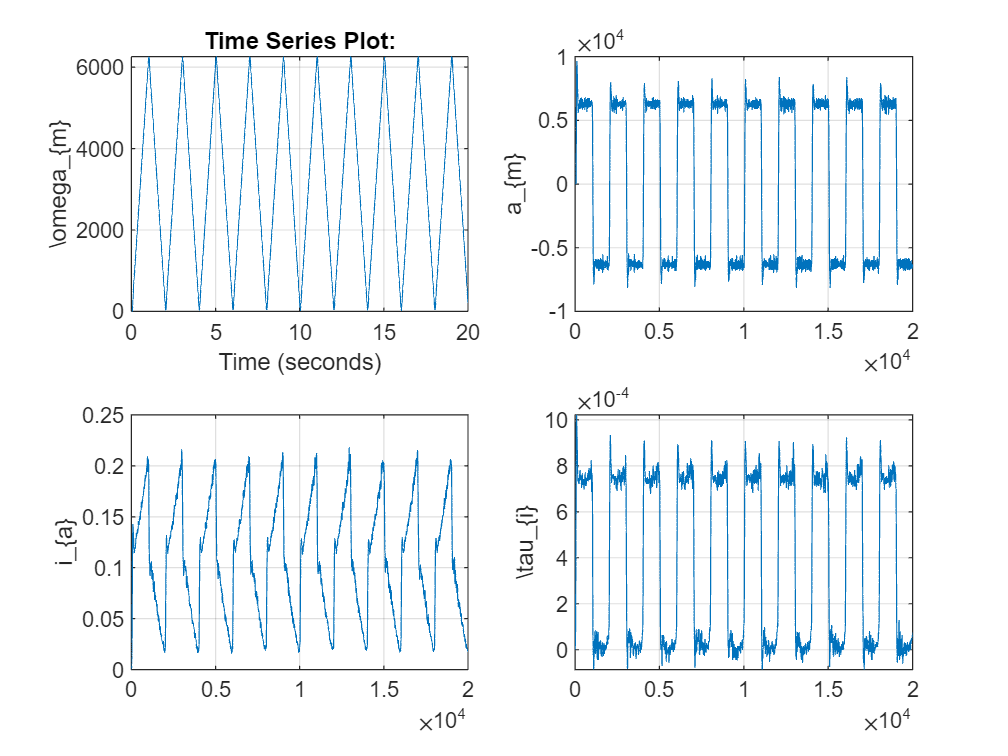

figure
subplot(2,2,1)
plot(proc.wm)
ylabel('\omega_{m}')

grid on

subplot(2,2,2)
plot(proc.am)
ylabel('a_{m}')

grid on

subplot(2,2,3)
plot(proc.iaf)
ylabel('i_{a}')

grid on

subplot(2,2,4)
plot(est.taui)
ylabel('\tau_{i}')

grid on

**Estimate of the equivalent inertia**

TODO --> Old code not available :(

est.Je_l = zeros(10,1);
for i = 0:9
    est.Je_l(i+1) = [est.tauimean(2*i+1) - est.tauimean(2*i+2)]/[est.am(2*i+1) - est.am(2*i+2)];
end
est.Je = mean(est.Je_l);

%CHANGE NAME EVERY EXPERIMENT
save("Je.mat","est");